## Navigation Ability = 0

### plot trajectories

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

figure
hold on
plot(out_mortcost,out_kincost,'.')

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title(strcat(['nmax = ',num2str(nmax)]))
grid on
legend off
hold off

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\trajectories_nmax0.jpg')

## Navigation Ability = 1

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_1\fitness_surface_lg.mat')

all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
%% 3D surface: mort and kin comp vs fitness
f = fit([out_mortcost out_kincost],out_fitness,"poly11");
plot(f,[out_mortcost out_kincost],out_fitness)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([47.70 39.15])


figure
clf
hold on
plot(f)
plot3(out_mortcost, out_kincost,out_fitness,'ok','MarkerFaceColor','k')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([0 90])
a = colorbar;
a.Label.String = 'Fitness';
hold off

% scatterplot, with bands identified as constant v0
figure
scatter(all,'Mortality','KinComp','ColorVariable','v0','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'v0 (probability of staying home)';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')

### plot trajectories

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_1\fitness_surface_lg.mat')

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

figure
hold on
plot(out_mortcost,out_kincost,'.')

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title(strcat(['nmax = ',num2str(nmax)]))
grid on
legend off
hold off

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\trajectories_nmax1.jpg')

## Navigation Ability = 2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_2\fitness_surface_lg.mat')

all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
%% 3D surface: mort and kin comp vs fitness
f = fit([out_mortcost out_kincost],out_fitness,"poly11");
plot(f,[out_mortcost out_kincost],out_fitness)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([47.70 39.15])


figure
clf
hold on
plot(f)
plot3(out_mortcost, out_kincost,out_fitness,'ok','MarkerFaceColor','k')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([0 90])
a = colorbar;
a.Label.String = 'Fitness';
hold off

% scatterplot, with bands identified as constant v0
figure
scatter(all,'Mortality','KinComp','ColorVariable','v0','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'v0 (probability of staying home)';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')


### plot trajectories

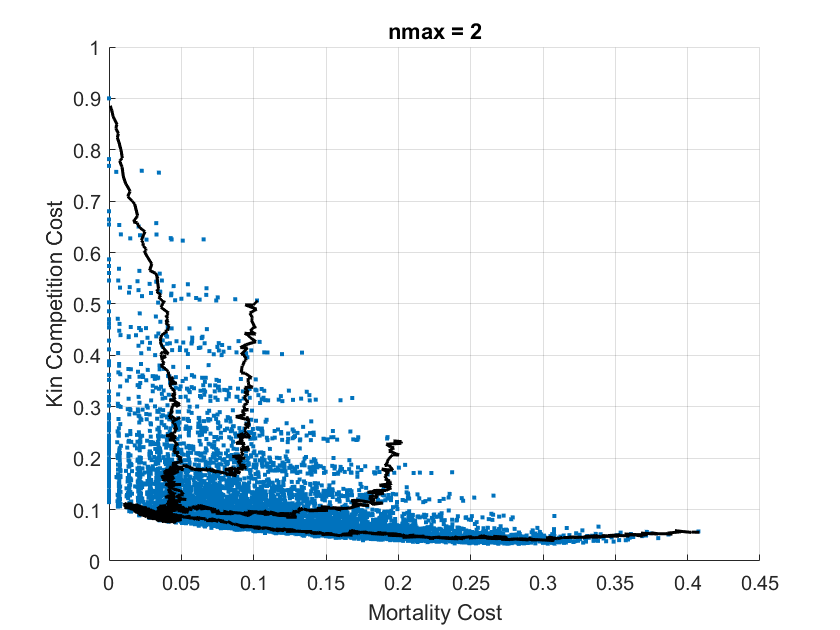

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_2\fitness_surface_lg.mat')

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

figure
hold on
plot(out_mortcost,out_kincost,'.')

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title(strcat(['nmax = ',num2str(nmax)]))
grid on
legend off
hold off

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\trajectories_nmax2.jpg')